# Darknet Importer and Exporter (yolov3/v4-matlab)

This respository uses simplified and minimal code to reproduce the yolov3 / yolov4 detection networks and darknet classification networks. The highlights are as follows:

- Support original version of darknet model;

- Support training, inference, import and export of "*** .cfg**", "*** .weights**" models;

- Support the latest[ yolov3, yolov4](https://github.com/AlexeyAB/darknet) models;

- Support darknet classification model;

- Support all kinds of indicators such as feature map size calculation, flops calculation and so on.

本库代码比pytorch和tensorflow等其他框架更具可读性和精简性！

These code is highly readable and more brief than other frameworks such as pytorch and tensorflow!

但是不包含各种训练数据增强tricks！

But it does not contain various training data augmentation tricks!

目前测试能导入和导出[官网1](https://github.com/pjreddie/darknet/tree/master/cfg)、[官网2](https://github.com/AlexeyAB/darknet/tree/master/cfg)绝大多数分类网络和检测网络，包括但不局限于以下网络。

alexnet.cfg

cifar.cfg

darknet.cfg 

darknet19.cfg

darknet19_448.cfg

darknet53.cfg 

darknet9000.cfg

 densenet201.cfg 

extraction.cfg

extraction.conv.cfg

 extraction22k.cfg tiny.cfg

tiny.cfg

yolov3-tiny.cfg

yolov3.cfg

yolov4.cfg

并且能够计算导入网络的[特征图大小](https://ww2.mathworks.cn/help/deeplearning/ug/layers-of-a-convolutional-neural-network.html)**，**[**FLOPs，**](https://en.wikipedia.org/wiki/FLOPS)[参数个数](https://ww2.mathworks.cn/help/deeplearning/ug/layers-of-a-convolutional-neural-network.html)。

addpath('./CustomLayers/','./utils/')

## 1、示例一：导入模型示例

从[https://pjreddie.com/darknet/imagenet/](https://pjreddie.com/darknet/imagenet/) 找到Pre_Trained Models的下载链接并点击下载，比如使用darknet19

cfg_file = 'cfg/darknet19.cfg';
weight_file = 'weights/darknet19.weights';
[mynet,hyperParams,numsNetParams,FLOPs] = importDarknetNetwork(cfg_file,weight_file);

This module No: 2 [convolutional],have #params:1024      ,FLops:67108864    ,feature map size:(256*256)
This module No: 4 [convolutional],have #params:18752     ,FLops:307232768   ,feature map size:(128*128)
This module No: 6 [convolutional],have #params:74368     ,FLops:304611328   ,feature map size:( 64* 64)
This module No: 7 [convolutional],have #params:8512      ,FLops:34865152    ,feature map size:( 64* 64)
This module No: 8 [convolutional],have #params:74368     ,FLops:304611328   ,feature map size:( 64* 64)
This module No:10 [convolutional],have #params:296192    ,FLops:303300608   ,feature map size:( 32* 32)
This module No:11 [convolutional],have #params:33408     ,FLops:34209792    ,feature map size:( 32* 32)
This module No:12 [convolutional],have #params:296192    ,FLops:303300608   ,feature map size:( 32* 32)
This module No:14 [convolutional],have #params:1182208   ,FLops:302645248   ,feature map size:( 16* 16)
This module No:15 [convolutional],have #params:132352    ,FLops:

analyzeNetwork(mynet)

% 获取classesNames
fid = fopen('utils/imagenet_shortnames_list.txt','r');
cls = textscan(fid, '%s', 'Delimiter',{'\n'});
classesNames = cls{1};
fclose(fid);

%  预测top5
img = imread('peppers.png');
input_size = mynet.Layers(1).InputSize;
img =im2single(imresize(img,input_size(1:2)));
scores = predict(mynet,img);
rank_k = 5;
[max_scores,ids] = maxk(scores,rank_k,2);
for i = 1:rank_k
    predictLabel = classesNames{ids(i)};
    predictScore = max_scores(i);
    fprintf('top%d, predictLabel:%-20s,predictScore:%.2f\n',i,predictLabel,predictScore);
end

top1, predictLabel:bell pepper         ,predictScore:0.83
top2, predictLabel:cucumber            ,predictScore:0.05
top3, predictLabel:grocery store       ,predictScore:0.02
top4, predictLabel:acorn squash        ,predictScore:0.01
top5, predictLabel:maraca              ,predictScore:0.01


## 2、示例二：导入部分层和权重

cutoffModule = 15;
[lgraphWeight,hyperParams,numsNetParams,FLOPs] = importDarknetWeights(cfg_file,weight_file,cutoffModule);

This module No: 2 [convolutional],have #params:1024      ,FLops:67108864    ,feature map size:(256*256)
This module No: 4 [convolutional],have #params:18752     ,FLops:307232768   ,feature map size:(128*128)
This module No: 6 [convolutional],have #params:74368     ,FLops:304611328   ,feature map size:( 64* 64)
This module No: 7 [convolutional],have #params:8512      ,FLops:34865152    ,feature map size:( 64* 64)
This module No: 8 [convolutional],have #params:74368     ,FLops:304611328   ,feature map size:( 64* 64)
This module No:10 [convolutional],have #params:296192    ,FLops:303300608   ,feature map size:( 32* 32)
This module No:11 [convolutional],have #params:33408     ,FLops:34209792    ,feature map size:( 32* 32)
This module No:12 [convolutional],have #params:296192    ,FLops:303300608   ,feature map size:( 32* 32)
This module No:14 [convolutional],have #params:1182208   ,FLops:302645248   ,feature map size:( 16* 16)
This module No:15 [convolutional],have #params:132352    ,FLops:

analyzeNetwork(lgraphWeight)

## 3、示例三：导出mobilenetV2模型

mynet = mobilenetv2;
hyperParams = [];
if isempty(hyperParams)
    hyperParams = struct('batch',64,...
        'subdivisiions',1,...
        'height',mynet.Layers(1).InputSize(1),...
        'width',mynet.Layers(1).InputSize(2),...
        'channels',mynet.Layers(1).InputSize(3),...
        'momentum',0.9,...
        'max_crop',256,...
        'learning_rate',0.01,...
        'policy','poly',...
        'power',4,...
        'max_batches',600000,...
        'angle',7,...
        'saturation',0.75,...
        'exposure',0.75,...
        'aspect',0.75);
end
exportDarkNetNetwork(mynet,hyperParams,'cfg/mobilenetv2.cfg','weights/mobilenetv2.weights');

---


## 4、示例四：导入yolov3/v4

比如使用[yolov3-tiny.cfg](https://github.com/pjreddie/darknet/blob/master/cfg/yolov3-tiny.cfg)

cfgfile = 'cfg/yolov4.cfg';
weightfile = 'weights/yolov4.weights';

weightfile = 'weights/yolov4.weights'

[lgraphLayer,hyperParams]= importDarknetWeights(cfgfile,weightfile);

This module No: 2 [convolutional],have #params:1024      ,FLops:378535936   ,feature map size:(608*608)
This module No: 3 [convolutional],have #params:18752     ,FLops:1732984832  ,feature map size:(304*304)
This module No: 4 [convolutional],have #params:4416      ,FLops:408109056   ,feature map size:(304*304)
This module No: 6 [convolutional],have #params:4416      ,FLops:408109056   ,feature map size:(304*304)
This module No: 7 [convolutional],have #params:2208      ,FLops:204054528   ,feature map size:(304*304)
This module No: 8 [convolutional],have #params:18752     ,FLops:1732984832  ,feature map size:(304*304)
This module No:10 [convolutional],have #params:4416      ,FLops:408109056   ,feature map size:(304*304)
This module No:12 [convolutional],have #params:8512      ,FLops:786644992   ,feature map size:(304*304)
This module No:13 [convolutional],have #params:74368     ,FLops:1718198272  ,feature map size:(152*152)
This module No:14 [convolutional],have #params:8512      ,FLops:

analyzeNetwork(lgraphLayer)


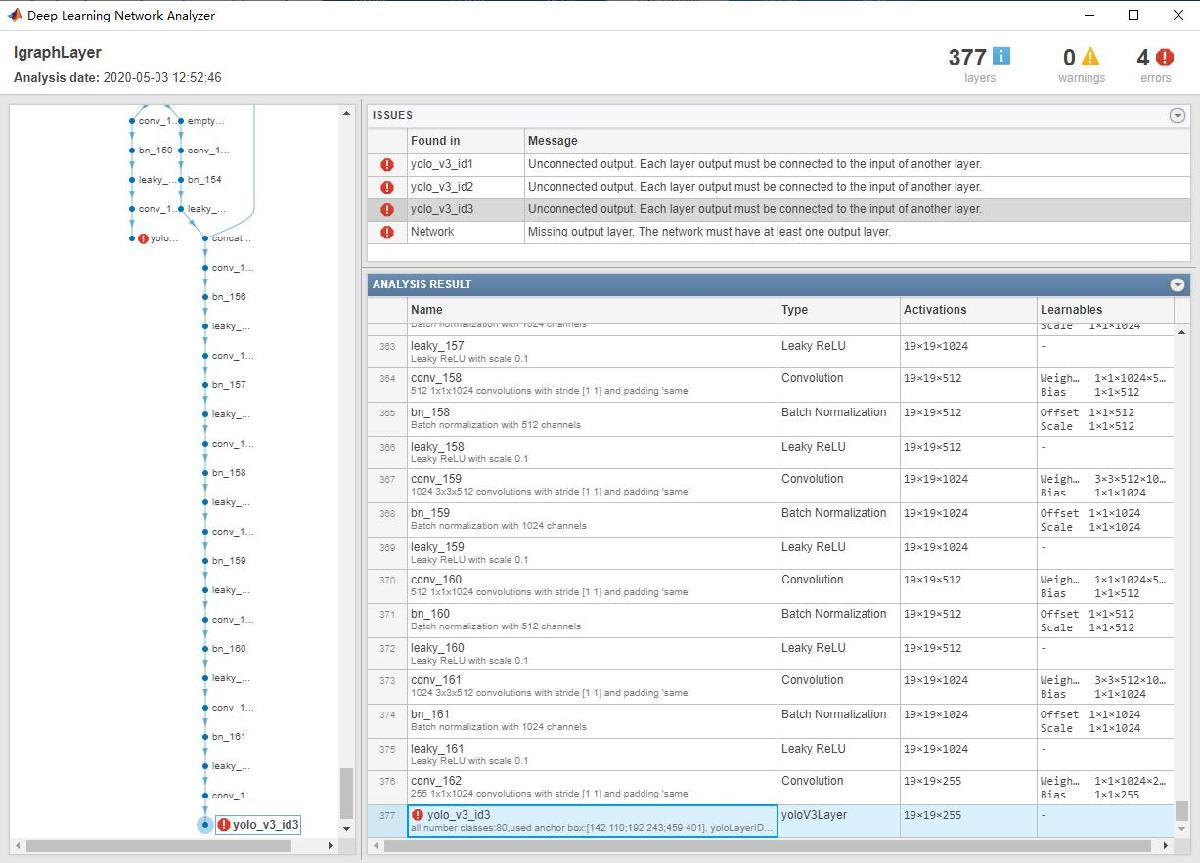

## 5、示例五：导出yolov3/v4整个网络

matlabExport_cfg = 'matlabExportYoloV4.cfg';
matlabExport_w = 'matlabExportYoloV4.weights';
dlnet = dlnetwork(lgraphLayer);
exportDarkNetNetwork(dlnet,hyperParams,matlabExport_cfg,matlabExport_w);

## 6、示列六：yolov3/v4视频流在线检测识别

%% custom input
% clear all % 如果更换模型，需重置静态函数(影响性能)，否则可以不用清理
cfg_file = 'cfg/yolov4.cfg';
weight_file = 'weights/yolov4.weights';
throushold = 0.5;
NMS = 0.4;

%% import all classes
fid = fopen('coco.names','r');
names = textscan(fid, '%s', 'Delimiter',{'   '});
fclose(fid);classesNames = categorical(names{1});
RGB = randi(255,length(classesNames),3);

%% 摄像头视频流识别
cap = webcam();
player = vision.DeployableVideoPlayer();
image = cap.snapshot();
step(player, image);

while player.isOpen()
    image = cap.snapshot();
    t1 = tic;
    outFeatures = yolov3v4Predict(cfg_file,weight_file,image);% M*(5+nc) ,为[x,y,w,h,Pobj,p1,p2,...,pn]
    fprintf('预测耗时：%.2f 秒\n',toc(t1));% yolov4大概0.4秒，yolov3大概0.2秒，yolov3-tiny大概0.06秒
    
    %% 阈值过滤+NMS处理
    scores = outFeatures(:,5);
    outFeatures = outFeatures(scores>throushold,:);
    
    allBBoxes = outFeatures(:,1:4);
    allScores = outFeatures(:,5);
    [maxScores,indxs] = max(outFeatures(:,6:end),[],2);
    allScores = allScores.*maxScores;
    allLabels = classesNames(indxs);
    
    % NMS非极大值抑制
    if ~isempty(allBBoxes)
        [bboxes,scores,labels] = selectStrongestBboxMulticlass(allBBoxes,allScores,allLabels,...
            'RatioType','Min','OverlapThreshold',NMS);
        annotations = string(labels) + ": " + string(scores);
        [~,ids] = ismember(labels,classesNames);
        colors = RGB(ids,:);
        image = insertObjectAnnotation(image,...
            'rectangle',bboxes,cellstr(annotations),...
            'Color',colors,...
            'LineWidth',3);
    end
    step(player,image);
end

This module No: 2 [convolutional],have #params:1024      ,FLops:378535936   ,feature map size:(608*608)
This module No: 3 [convolutional],have #params:18752     ,FLops:1732984832  ,feature map size:(304*304)
This module No: 4 [convolutional],have #params:4416      ,FLops:408109056   ,feature map size:(304*304)
This module No: 6 [convolutional],have #params:4416      ,FLops:408109056   ,feature map size:(304*304)
This module No: 7 [convolutional],have #params:2208      ,FLops:204054528   ,feature map size:(304*304)
This module No: 8 [convolutional],have #params:18752     ,FLops:1732984832  ,feature map size:(304*304)
This module No:10 [convolutional],have #params:4416      ,FLops:408109056   ,feature map size:(304*304)
This module No:12 [convolutional],have #params:8512      ,FLops:786644992   ,feature map size:(304*304)
This module No:13 [convolutional],have #params:74368     ,FLops:1718198272  ,feature map size:(152*152)
This module No:14 [convolutional],have #params:8512      ,FLops:

预测耗时：206.58 秒
预测耗时：0.48 秒
预测耗时：0.49 秒
预测耗时：0.50 秒
预测耗时：0.51 秒
预测耗时：0.45 秒
预测耗时：0.47 秒
预测耗时：0.45 秒
预测耗时：0.44 秒
预测耗时：0.52 秒
预测耗时：0.52 秒
预测耗时：0.51 秒
预测耗时：0.43 秒
预测耗时：0.51 秒
预测耗时：0.42 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.42 秒
预测耗时：0.44 秒
预测耗时：0.42 秒
预测耗时：0.44 秒
预测耗时：0.42 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.43 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.44 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.44 秒
预测耗时：0.41 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.43 秒
预测耗时：0.40 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.43 秒
预测耗时：0.46 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.41 秒
预测耗时：0.42 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.44 秒
预测耗时：0.42 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.41 秒
预测耗时：0.43 秒
预测耗时：0.42 秒
预测耗时：0.42 秒
预测

release(player);

